# Explore **PASSIVE** rotations and **EULER rates**

In this tutorial we're going to look at how the EULER rates of a rigid body can be determined from the BODY rates of the rigid body.  We'll see that there are certain angular poses that result in a matrix singularity which in turn prevents us from transforming from body rates to Euler rates.  This tutorial demonstrates how PASSIVE rotation matrices can be applied.

**Why are we doing this ?**

$\bullet $Before we can create a 6-DOF model of a vehicle (eg: a quadcopter), we need to get comfortable with certain concepts.  Concepts such as PASSIVE rotation matrices.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Review the concept of PASSIVE rotation matrices :

Consider the following scenario: 

- We have a data point $P$.

- We have a fixed frame called the **G-fame.**

- We know the *(x,y) *co-ordinates of the point $P$ in this **G-fame** and refer to this as ${^GP}$.

- We then rotate the **B-frame** relative to the fixed **G-frame**. 

We now want to know what the co-ordinate of the point $P$ is relative to this new **B-frame, **ie: what is ${^BP}$ ?  This scenario is shown in the figure below:

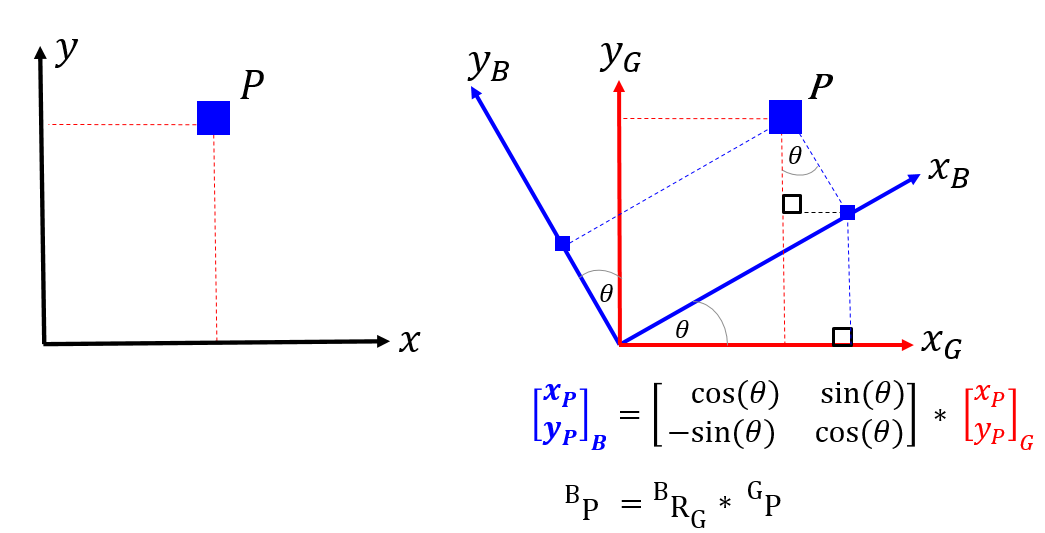 

A **PASSIVE** rotation matrix, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

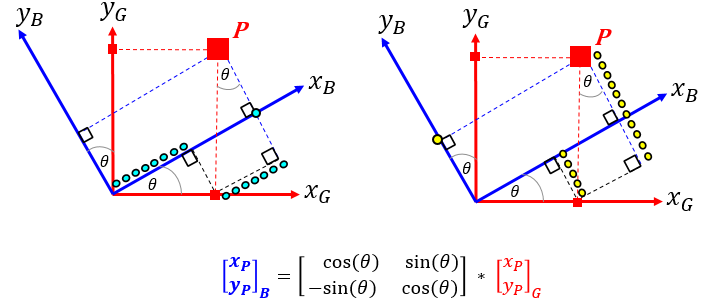

## An example of 3 successive PASSIVE rotations

Say we have a fixed G-frame. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 3 LOCAL axes rotations which will result in a newly orientated B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:


$$\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$$


    OR, in a more compact form as:


$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


## Create a passive rotation object

syms phi theta psi
OBJ_P = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [phi, theta, psi], 'SYM')

OBJ_P =   bh_rot_passive_G2B_CLS with properties:

        ang_units: SYM
    num_rotations: 3
          dir_1st: D1Z
          dir_2nd: D2Y
          dir_3rd: D3X
          ang_1st: [1x1 sym]
          ang_2nd: [1x1 sym]
          ang_3rd: [1x1 sym]


## Here are the PASSIVE rotation matrices

R1 = OBJ_P.get_R1

$$R1 = \left(\begin{array}{ccc} \cos\left(\phi \right) & \sin\left(\phi \right) & 0\\ -\sin\left(\phi \right) & \cos\left(\phi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2 = OBJ_P.get_R2

$$R2 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

R3 = OBJ_P.get_R3

$$R3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## Calculate the Direction Cosine Matrix  ${^{B}}R_G $

Recall we earlier said:          $^{B}v  = {^{B}}R_G *  {^{G}}v$

bRg = R3 * R2 * R1

$$bRg = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\phi \right) & -\sin\left(\theta \right)\\ \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

As a "short distraction" .... it's nice to know I can automatically convert this into a MATLAB function.  NOTE: we're specifying the order of the input variables for the function that gets generated.

matlabFunction(bRg,'File','bh_autogen_bRg','Optimize',false, 'Vars', {'phi','theta', 'psi'});

% look at the first 6 lines of this autogenerated file
dbtype('bh_autogen_bRg', '1:6')


1     function bRg = bh_autogen_bRg(phi,theta,psi)
2     %BH_AUTOGEN_BRG
3     %    BRG = BH_AUTOGEN_BRG(PHI,THETA,PSI)
4     
5     %    This function was generated by the Symbolic Math Toolbox version 7.0.
6     %    06-Jun-2016 08:05:58


## Explore EULER rates

As we apply these local frame rotations, we can represent the angular rates of the rotating frames in the LOCAL frame co-ordinates. These local frame co-ordinates can then be converted into co-ordinates expressed in the final B frame.  For example, during each of the local axes rotations we can think of there being a START frame and an END frame:

      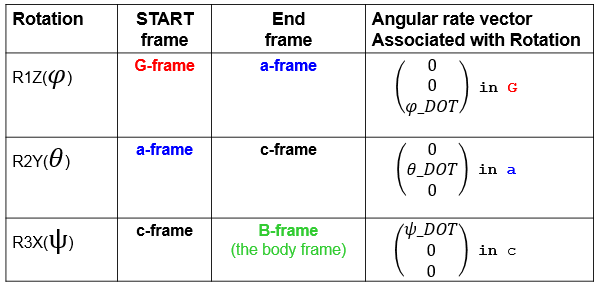

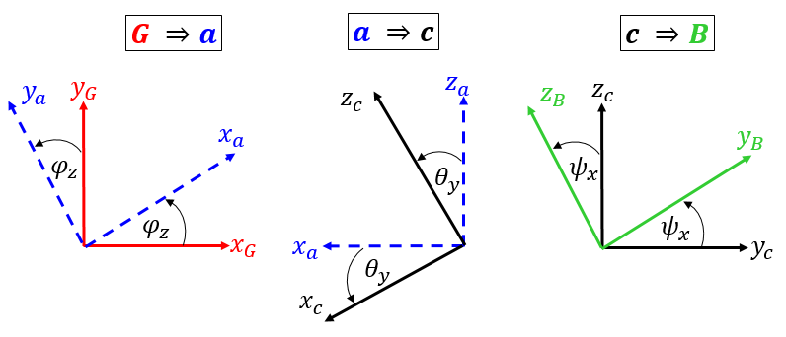

We can express each of the local frame angular velocities into their corresponding components in the final B frame - and we'll use PASSIVE rotation matrices to do this:

syms phi_dot  theta_dot  psi_dot

aRg = R1;
cRa = R2;
bRc = R3;

wb_part_1 = bRc * cRa * aRg * [0;0;phi_dot]   % convert local G into B

$$wb\_part\_1 = \left(\begin{array}{c} -\phi_{\mathrm{dot}}\,\sin\left(\theta \right)\\ \phi_{\mathrm{dot}}\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \phi_{\mathrm{dot}}\,\cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

wb_part_2 = bRc * cRa *       [0;theta_dot;0] % convert local a into B

$$wb\_part\_2 = \left(\begin{array}{c} 0\\ \theta_{\mathrm{dot}}\,\cos\left(\psi \right)\\ -\theta_{\mathrm{dot}}\,\sin\left(\psi \right) \end{array}\right)$$

wb_part_3 = bRc *             [psi_dot;0;0]   % convert local c into B

$$wb\_part\_3 = \left(\begin{array}{c} \psi_{\mathrm{dot}}\\ 0\\ 0 \end{array}\right)$$

## The total angular velocity expressed in the BODY B frame is therefore

We can now construct the total angular velocity vector expressed in components of the final B frame.


$$_G^{B}\omega_b \equiv \omega_b = f( \phi_{dot}, \theta_{dot}, \psi_{dot}) $$
 

wb = wb_part_1 + wb_part_2 + wb_part_3

$$wb = \left(\begin{array}{c} \psi_{\mathrm{dot}}-\phi_{\mathrm{dot}}\,\sin\left(\theta \right)\\ \theta_{\mathrm{dot}}\,\cos\left(\psi \right)+\phi_{\mathrm{dot}}\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \phi_{\mathrm{dot}}\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\theta_{\mathrm{dot}}\,\sin\left(\psi \right) \end{array}\right)$$

## We can write the angular velocity vector $\omega_b$ as a MATRIX equation

Let's say that:  $ \omega_b = \pmatrix{p \cr q \cr r}
$

We can write a matrix equation of the form **A.x = b** that describes the relationship between the body rates $\omega_b$ and the Euler rates: 


$$ A \times x = b $$



$$A \times   \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  =  \pmatrix{p \cr q \cr r}  \equiv \omega_b$$
  

syms p q r

    x = [phi_dot, theta_dot, psi_dot].'

$$x = \left(\begin{array}{c} \phi_{\mathrm{dot}}\\ \theta_{\mathrm{dot}}\\ \psi_{\mathrm{dot}} \end{array}\right)$$

    
[A,b] = equationsToMatrix(  wb(1)==p, ...
                            wb(2)==q, ...
                            wb(3)==r, ...
                            x)

$$A = \left(\begin{array}{ccc} -\sin\left(\theta \right) & 0 & 1\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ \cos\left(\psi \right)\,\cos\left(\theta \right) & -\sin\left(\psi \right) & 0 \end{array}\right)$$

$$b = \left(\begin{array}{c} p\\ q\\ r \end{array}\right)$$

## **ATTENTION:   The SINGULARITY between BODY rates and EULER rates**

From the Matrix equation computed above there is actually an angle that causes the determinant of **A** to be ZERO, and hence prevents us from solving for the Euler rates (at that angle) iff we know the body rates $\omega_b$.  The angle that causes this problem is the rotation about the local Y axis, ie: the angle $\theta$. Specifically it is when $\theta = 90^o$.  We can see this by first computing the determinant of *A .*

det_A = simplify( det(A) )

$$det\_A = -\cos\left(\theta \right)$$

And then solving for its roots. 

solve( det_A ==0 ) 

$$ans = \frac{\pi }{2}$$

So this tells us that as soon as our vehicle has a pitch angle of 90 degrees, that our chosen Euler angle sequence simply canNOT be used to convert body rates $\omega_b$ into Euler rates.  So?  So, if you think your vehicle will pitch by 90 degrees ... ***AND you're wanting to calculate EULER rates from body rates*** .... then you'll need to consider an alternate form of describing your vehicle's pose (eg: quaternions, or integrating directly the DCM) 

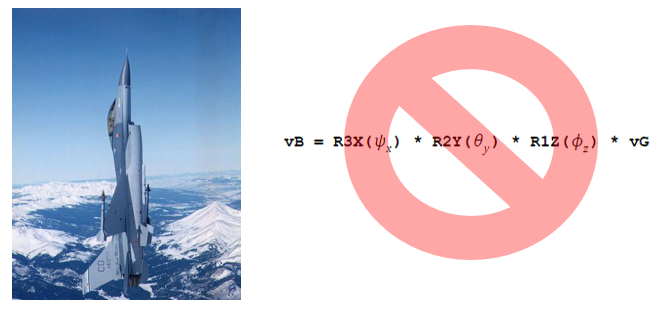

## Let's compute Euler rates from our body rates $\omega_b$

Assuming our vehicle does NOT have a pitch angle of 90 degrees, then we can use the results of the previous section to calculate the Euler rates from our body rates $\omega_b$.

      $Euler_{rates} \equiv  \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  = A^{-1} * \omega_b$       where      $ \omega_b = \pmatrix{p \cr q \cr r}
$

euler_rates = inv(A) * [p; q; r];
euler_rates = simplify(euler_rates)

$$euler\_rates = \left(\begin{array}{c} \frac{r\,\cos\left(\psi \right)+q\,\sin\left(\psi \right)}{\cos\left(\theta \right)}\\ q\,\cos\left(\psi \right)-r\,\sin\left(\psi \right)\\ \frac{p\,\cos\left(\theta \right)+r\,\cos\left(\psi \right)\,\sin\left(\theta \right)+q\,\sin\left(\psi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} \end{array}\right)$$

## We can write the Euler rates vector as a MATRIX equation

Similarly to what we did earlier we can write a matrix equation that describes the relationship between the body rates $\omega_b$ and the Euler rates:

         
$$K \times  \omega_b =  Euler_{rates}$$
      

     
$$K \times  \pmatrix{p \cr q \cr r} =  
\pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} } $$


   
$$K \times x = b$$
  

     x = [p,q,r].'

$$x = \left(\begin{array}{c} p\\ q\\ r \end{array}\right)$$


[K,b] = equationsToMatrix(  euler_rates(1)==phi_dot,   ...
                            euler_rates(2)==theta_dot, ...
                            euler_rates(3)==psi_dot,   ...
                            x)

$$K = \left(\begin{array}{ccc} 0 & \frac{\sin\left(\psi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\psi \right)}{\cos\left(\theta \right)}\\ 0 & \cos\left(\psi \right) & -\sin\left(\psi \right)\\ 1 & \frac{\sin\left(\psi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\psi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} \end{array}\right)$$

$$b = \left(\begin{array}{c} \phi_{\mathrm{dot}}\\ \theta_{\mathrm{dot}}\\ \psi_{\mathrm{dot}} \end{array}\right)$$